# **Cruise Control using PID controller**

clc; % Clear the command window
clear all; % Clear all variables from the workspace
close all; % Close all figure windows

### **open loop step response**

plant_tf =
 
       1
  -----------
  1000 s + 50
 
Continuous-time transfer function.



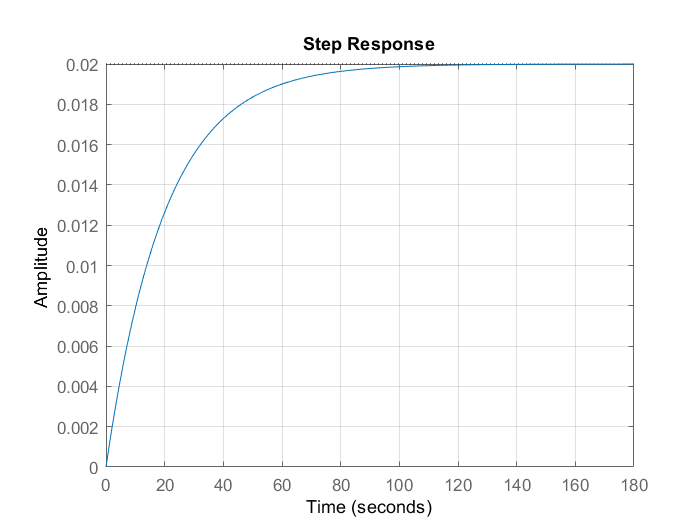

m = 1000;   % Vehicle mass (Kg)
b = 50;     % Damping coefficient (N·s/m)

% Define the transfer function variable 's'
S = tf("s");

% Create the transfer function for the plant (vehicle dynamics)
plant_tf = 1/(m*S + b);

% Simulate the step response of the open-loop system
[y, ~] = step(plant_tf);
stepplot(plant_tf); % Plot the step response
grid on; % Enable the grid on the plot

% rlocusplot(plant_tf) % Uncomment to plot the root locus of the plant

### **Calculate system properties from the step response**

sysprop = stepinfo(plant_tf, 'RiseTimeThreshold', [0.1 0.9]);

sysprop = struct with fields:
        RiseTime: 43.9401
    SettlingTime: 78.2415
     SettlingMin: 0.0181
     SettlingMax: 0.0200
       Overshoot: 0
      Undershoot: 0
            Peak: 0.0200
        PeakTime: 210.9168


steady_state_error = 0.9800

sysprop % Display the system properties
steady_state_error = abs(1 - y(end)); % Calculate the steady-state error

### PID controller parameters

KP = 340

KP = 340

KI = 50

KI = 50

KD = 100

KD = 100

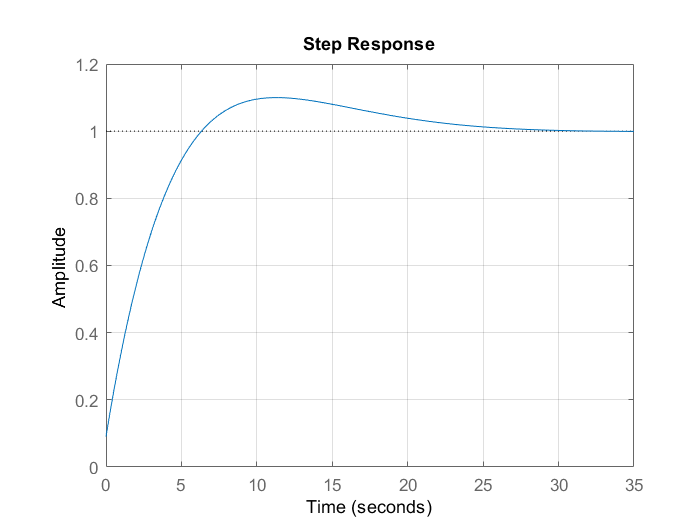

rise_time = 4.5992

max_overshoot = 9.9960

steady_state_err = 0.0057


% Create the PID controller transfer function
control_tf = pid(KP, KI, KD);

% Create the closed-loop transfer function by combining the PID controller and plant
closedLoop_tf = feedback(control_tf * plant_tf, 1);

% Simulate the step response of the closed-loop system
[y, ~] = step(closedLoop_tf);
stepplot(closedLoop_tf); % Plot the step response
grid on; % Enable the grid on the plot

% Calculate system properties from the closed-loop step response
sysprop = stepinfo(closedLoop_tf, 'RiseTimeThreshold', [0.1 0.9]);
rise_time = sysprop.RiseTime; % Extract rise time
max_overshoot = sysprop.Overshoot; % Extract maximum overshoot
steady_state_err = abs(1 - y(end)) * 100; % Calculate steady-state error as a percentage